#### Program to add a channel mesh to an existing background mesh

Initialize mesh2d

addpath([UTILS_PATH '/matlab/mesh2d']);  % Customize this for your mesh2d installation
initmsh();

Change the current working directory

cd('\\wsl$\Ubuntu\home\sbunya\GitHub\adcircutils\examples\channelmodeling\channelpaving\example1')   % Customize this for your installation

Setting parameters

% Default parameters
opts.rep_dist_adjust = 1.0;    % Adjustment scale for the local representative mesh size
removal_range = 8.0;      % Range to remove elements from the channel center line nodes as a ratio to the center line node distance
reject_margin = -0.0;     % The ratio to the representative original mesh element size to be used for rejection judgement
max_num_rejected = 10000; % Maximum number of rejections of the randomly generated nodes
niter_relax = 10;         % Number of mesh relaxation iteration
radius_to_merge_shppoints = 0.1; % Radius to determine points to be merged
ignore_depth_in_channel = true; % Flag to decide if the depth along the channels should be ignored when the depths on the banks and floodplains are interpolated.
plot_level = 0;           % Specificaions of the vervose level for intermediate figures
rseed = 1;                % Random seed
channel_smoothing_span = 1; % smoothing parameter for width and depth. No smoothing applied if the value is 1 
spacing_link_with_width = false; % Flag to set spacing linked with width
ignore_depth_in_channel = true; % Flag to ignore the depth in the channel in the original mesh when the depths on the floodplain nodes are interpolated.
nudge_depth_at_channel_ends = false; % Flag to not exclude original mesh depths at the end of channels when interpolating the depths at floodplain nodes
set_initial_river_elevation = true; % Flag to set the nodal attribute, "initial_river_elevation"
no_channelmesh = false;    % Flag to not use the channel mesh
write_output = true;     % Flag to write output fort.14 and fort.13
do_renum = false;

pave_opts.output_mesh_prefix = 'ncv30.01a_fixingdepth';
pave_opts.radius_to_merge_shppoints = 0.1; % Radius to determine points to be merged
pave_opts.effective_width_ratio = 1.0;
pave_opts.max_width = 100.0;
pave_opts.min_width = 0.0;
pave_opts.max_channel_depth = max_channel_depth;
pave_opts.min_channel_depth = min_channel_depth;
pave_opts.in14 = in14;
pave_opts.in13 = in13;
pave_opts.removal_range = removal_range;
pave_opts.rep_dist_adjust = rep_dist_adjust;
pave_opts.rseed = rseed;
pave_opts.reject_margin = reject_margin;
pave_opts.max_num_rejected = max_num_rejected;
pave_opts.niter_relax = niter_relax;
pave_opts.ignore_depth_in_channel = ignore_depth_in_channel;
pave_opts.nudge_depth_at_channel_ends = nudge_depth_at_channel_ends;
pave_opts.no_channelmesh = no_channelmesh;
pave_opts.set_initial_river_elevation = set_initial_river_elevation;
pave_opts.default_ndattrs = default_ndattrs;
pave_opts.channel_ndattrs = channel_ndattrs;
pave_opts.channel_smoothing_span = channel_smoothing_span;
pave_opts.spacing_link_with_width = spacing_link_with_width;
pave_opts.min_spacing = min_spacing;
pave_opts.min_condensed_nodes_spacing = min_condensed_nodes_spacing;
pave_opts.zshift = 0.0;
pave_opts.zshift_taper_elev_range = [0.0 0.0];
pave_opts.plot_level = plot_level;
pave_opts.write_output = write_output;
pave_opts.indomain_flowbc = indomain_flowbc;
pave_opts.do_renum = do_renum;
pave_opts.diffuse_depth = true;
pave_opts.diffuse_width = true;

dem = [];

Common settings

ignore_depth_in_channel = true;
no_channelmesh = false;
set_initial_river_elevation = true;
channel_smoothing_span = 3;
indomain_flowbc = true;
min_channel_depth = 0;
max_channel_depth = 100;

% Channel nodal attribute values
keys = ["mannings_n_at_sea_floor", ...
        "primitive_weighting_in_continuity_equation"];
defvalues = {0.02,0.03};
channelvalues = {0.02,0.1};
default_ndattrs = dictionary(keys,defvalues);
channel_ndattrs = dictionary(keys,channelvalues);

effective_width_ratio = 1.0;
max_width = 100.0;
min_width = 0.0;
resolution_common = 80.0;
min_spacing = 40.0; % m
min_condensed_nodes_spacing = 80.0; % m

output_mesh_prefix = 'ncv30.01a_fixingdepth';
plot_level = 0;           % Specificaions of the vervose level for intermediate figures

Read base mesh

in14 = './meshes/ncv30/ncv30.00c_ncv27.05ca1_roanoke.grd';
in13 = './meshes/ncv30/ncv30.00c_ncv27.05ca1_roanoke_updated.13';
m_org = msh('fname',in14,'aux',{in13});

INFO: An ADCIRC fort.14 file will be read...
read adcirc fort.14
ncv27.05ca1 based, Roanoke River upstream floodplain added
INFO: ADCIRC fort.13 file will be read...
ncv27.05ca1 based, Roanoke River upstream floodplain added
surface_directional_effective_roughness_length
surface_canopy_coefficient
mannings_n_at_sea_floor
primitive_weighting_in_continuity_equation
average_horizontal_eddy_viscosity_in_sea_water_wrt_depth
elemental_slope_limiter
wave_refraction_in_swan
sea_surface_height_above_geoid
initial_river_elevation
overland_reduction_factor
advection_state
condensed_nodes


m_new = m_org;

pave_opts.output_mesh_prefix = output_mesh_prefix;
pave_opts.radius_to_merge_shppoints = radius_to_merge_shppoints;
pave_opts.dem = dem;
pave_opts.effective_width_ratio = effective_width_ratio;
pave_opts.max_width = max_width;
pave_opts.min_width = min_width;
pave_opts.max_channel_depth = max_channel_depth;
pave_opts.min_channel_depth = min_channel_depth;
pave_opts.in14 = in14;
pave_opts.in13 = in13;
pave_opts.removal_range = removal_range;
pave_opts.rep_dist_adjust = rep_dist_adjust;
pave_opts.rseed = rseed;
pave_opts.reject_margin = reject_margin;
pave_opts.max_num_rejected = max_num_rejected;
pave_opts.niter_relax = niter_relax;
pave_opts.ignore_depth_in_channel = ignore_depth_in_channel;
pave_opts.nudge_depth_at_channel_ends = nudge_depth_at_channel_ends;
pave_opts.no_channelmesh = no_channelmesh;
pave_opts.set_initial_river_elevation = set_initial_river_elevation;
pave_opts.default_ndattrs = default_ndattrs;
pave_opts.channel_ndattrs = channel_ndattrs;
pave_opts.channel_smoothing_span = channel_smoothing_span;
pave_opts.spacing_link_with_width = spacing_link_with_width;
pave_opts.min_spacing = min_spacing;
pave_opts.min_condensed_nodes_spacing = min_condensed_nodes_spacing;
pave_opts.zshift = 0.0;
pave_opts.zshift_taper_elev_range = [0.0 0.0];
pave_opts.plot_level = plot_level;
pave_opts.write_output = write_output;
pave_opts.indomain_flowbc = indomain_flowbc;
pave_opts.do_renum = do_renum;
pave_opts.diffuse_depth = true;
pave_opts.diffuse_width = true;
pave_opts_common = pave_opts;

Channel paving - Roanoke

pave_opts.editname = 'roanoke'

pave_opts = struct with fields:
             output_mesh_prefix: 'ncv30.01a_fixingdepth'
      radius_to_merge_shppoints: 0.1000
                            dem: []
          effective_width_ratio: 1
                      max_width: 4000
                      min_width: 10
              max_channel_depth: 10.5000
              min_channel_depth: 2
                           in14: './meshes/ncv30/ncv30.00c_ncv27.05ca1_roanoke.grd'
                           in13: './meshes/ncv30/ncv30.00c_ncv27.05ca1_roanoke_updated.13'
                  removal_range: 50
                rep_dist_adjust: 1
                          rseed: 1
                  reject_margin: 0
               max_num_rejected: 10000
                    niter_relax: 10
        ignore_depth_in_channel: 1
    nudge_depth_at_channel_ends: 0
                 no_channelmesh: 0
    set_initial_river_elevation: 1
                default_ndattrs: dictionary (string ⟼ cell) with 2 entries
                channel_ndattrs: dictionary 

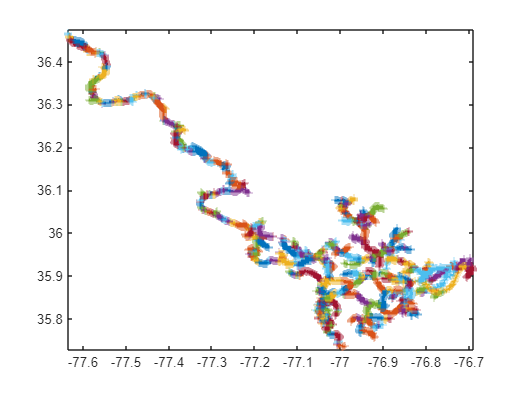

Timer: 1
Elapsed time is 2.612802 seconds.
Timer: 2
Elapsed time is 0.412842 seconds.
write adcirc fort.14
OceanMesh2D
Timer: 2
Elapsed time is 1.734211 seconds.
Timer: 4
Elapsed time is 0.000774 seconds.
Timer: 5
Elapsed time is 0.963354 seconds.
   115

diffusing depth ... loopcnt = 1, anynan_cnt = 64


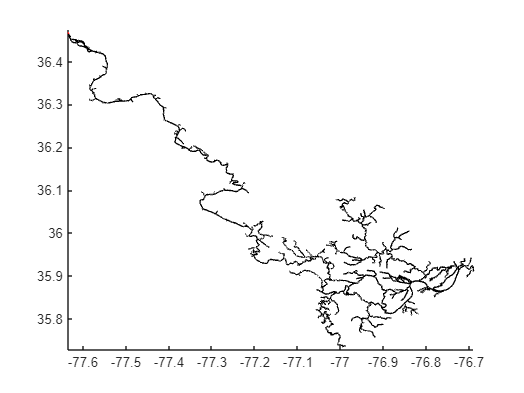

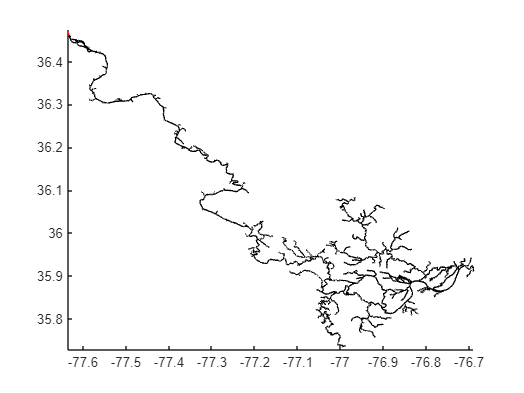

Timer: 6
Elapsed time is 82.563510 seconds.
Timer: 7
Elapsed time is 33.716055 seconds.
Timer: 8
Elapsed time is 0.076907 seconds.
Timer: 9
Elapsed time is 1.594666 seconds.
Timer: 10
Elapsed time is 1.204391 seconds.
Timer: 11-1
Elapsed time is 1.028916 seconds.
Timer: 11-2
Elapsed time is 0.179892 seconds.
Timer: 11
Elapsed time is 0.032794 seconds.
write adcirc fort.14
OceanMesh2D


pave_opts.resolution = resolution_common;
pave_opts.removal_range = 4000/pave_opts.resolution;
pave_opts.flowlinefile = 'gis_data/nhdp_hr_roanoke_4_DPWD_LG_Data_NoMaxW.geojson';
% pave_opts.zshift = -0.70;
% pave_opts.zshift_taper_elev_range = [0,2];
pave_opts.max_channel_depth = 10.5;
pave_opts.min_channel_depth = 2.0;
pave_opts.max_width = 4000.0;
pave_opts.min_width = 10.0;
pave_opts.spacing_link_with_width = false;
m_new = pave(m_new, pave_opts);

pave_opts = pave_opts_common;

output_mesh_prefix = 'ncv30.01a1';

in14 = './meshes/ncv30.01a_roanoke.grd_roanoke_handedited.grd';
in13 = './meshes/ncv30.01a_roanoke.grd_roanoke.13';
m = msh('fname',in14,'aux',{in13});

INFO: An ADCIRC fort.14 file will be read...
read adcirc fort.14
ncv27.05ca1 based, Roanoke River upstream floodplain added
INFO: ADCIRC fort.13 file will be read...
ncv27.05ca1 based, Roanoke River upstream floodplain added
surface_directional_effective_roughness_length
surface_canopy_coefficient
mannings_n_at_sea_floor
primitive_weighting_in_continuity_equation
average_horizontal_eddy_viscosity_in_sea_water_wrt_depth
elemental_slope_limiter
wave_refraction_in_swan
sea_surface_height_above_geoid
initial_river_elevation
overland_reduction_factor
advection_state
condensed_nodes



m_out = renum_mesh_and_condensednodes(m);

Initial bandwidth is 745461
Renumbered bandwidth is 3589
Renumbering the elevation specified boundary nodestrings...
Renumbering the flux boundary nodestrings...
Renumbering the fort.13...



m_out.title = output_mesh_prefix;
m_out.f13.ARGID = ['Nodal attrs for ' output_mesh_prefix];

out14 = ['./meshes/' output_mesh_prefix];
m_out.write(out14,{'13','14'});

write adcirc fort.14
ncv30.01a1


movefile([out14 '.14'],[out14 '.grd']);